# Dumbbell Secular Determinant

Computes analytical and numerical secular determinants and compares the results with each other as well as the squareroots of the eigenvalues.

### Create the graph

Creates the graph with both the uniform and Chebyshev discretizations so we can compare the eigenvalues of these two discretizations later

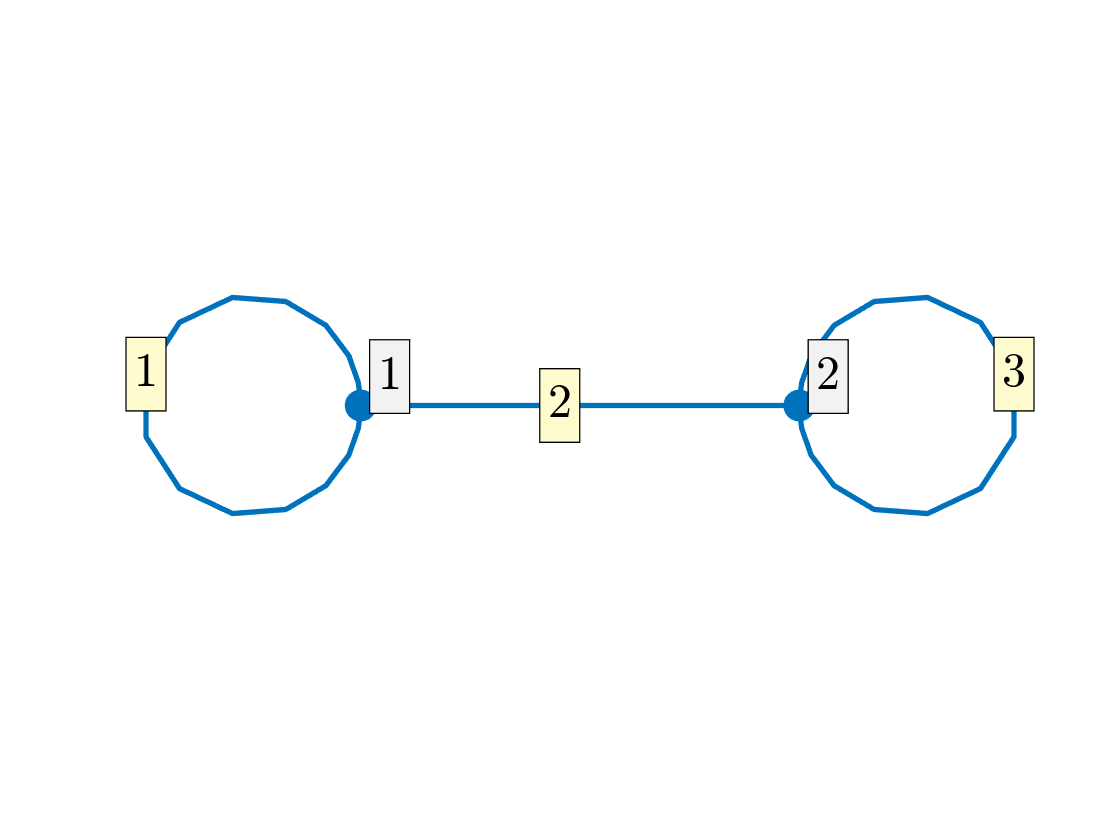

syms k
clf;
beta = 1;
robinCoeff = [beta beta];
Phi = quantumGraphFromTemplate('dumbbell','robinCoeff',robinCoeff,'discretization','Chebyshev','nx',16);
PhiU = quantumGraphFromTemplate('dumbbell','robinCoeff',robinCoeff,'discretization','Uniform','nx',64);
Phi.plot('layout')

## Numerical Secular Determinant

This converts the symbolic numerical secular determinant to a Matlab function then plots it and it's zeros

[SD,S,D] = Phi.secularDet;
disp('The numerical secular determinant is:')

The numerical secular determinant is:


disp(SD)

$$\begin{array}{l} -\frac{\sin\left(4\,x\right)-2\,x\,\cos\left(4\,x\right)-\sin\left(4\,x\right)\,\sigma_{1}+11\,x^{2}\,\sin\left(4\,x\right)-8\,x^{2}\,\cos\left(4\,x\right)\,\sigma_{3}-16\,x^{2}\,\sin\left(4\,x\right)\,\cos\left(2\,\pi \,x\right)+4\,x^{2}\,\cos\left(4\,x\right)\,\sigma_{2}+5\,x^{2}\,\sin\left(4\,x\right)\,\sigma_{1}+2\,x\,\cos\left(4\,x\right)\,\sigma_{1}+8\,x\,\sin\left(4\,x\right)\,\sigma_{3}-4\,x\,\sin\left(4\,x\right)\,\sigma_{2}}{18\,x^{2}+2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(4\,\pi \,x\right)\\ \sigma_{2}=\sin\left(4\,\pi \,x\right)\\ \sigma_{3}=\sin\left(2\,\pi \,x\right) \end{array}$$

(I should point out that this S matrix matches my analytic results.)

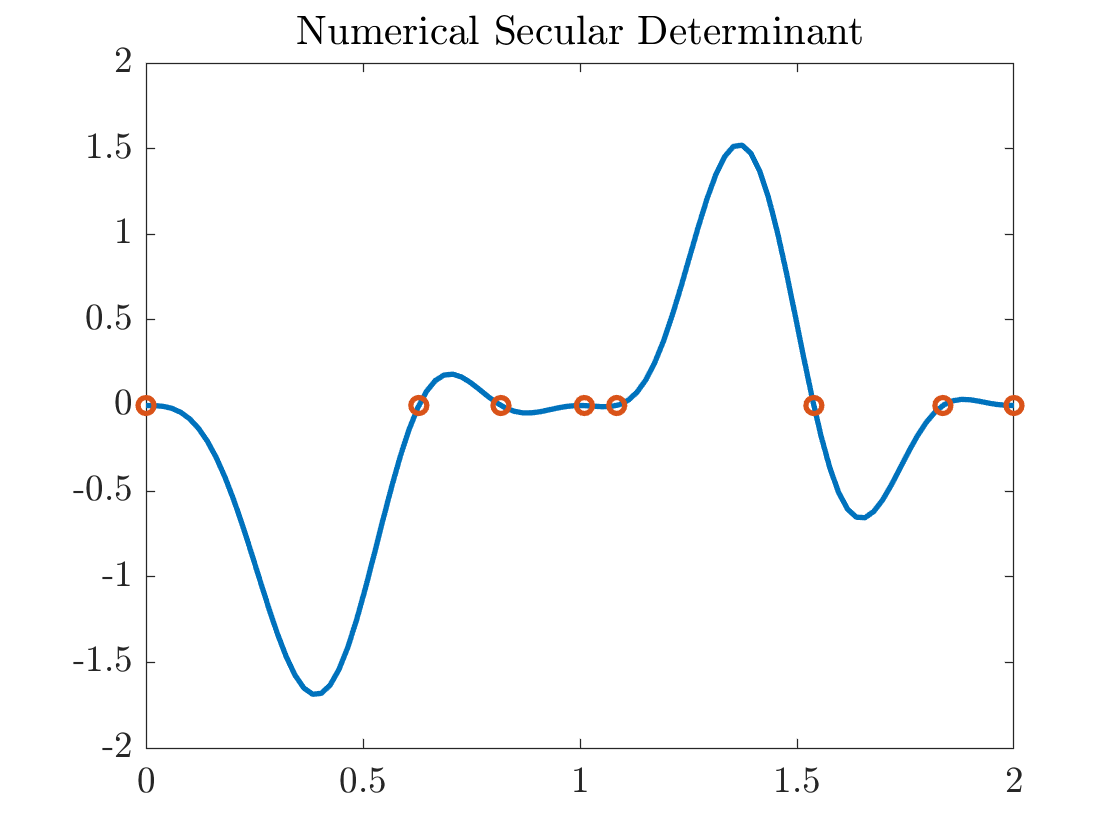

F=matlabFunction(SD);
x=linspace(0,2);
Fx=F(x);
clf
plot(x,Fx)
title('Numerical Secular Determinant')

% Finds zeros of F(x)
kmax=2;
signChanges=find(Fx(1:end-1).*Fx(2:end)<0);
nSignChanges=length(signChanges);
kstar=zeros(nSignChanges,1);
for n=1:nSignChanges
    kstar(n)=fzero(F,x(signChanges(n)+[0 1]));
end
min=islocalmin(Fx); min = find(min==1);
max=islocalmax(Fx); max = find(max==1);
minmax=union(min,max);
i=1;
doubleRoots=zeros(2,1);
for n=1:length(minmax)
    if abs(F(x(minmax(n))))<10^(-3)
        doubleRoots(i)=x(minmax(n));
        i=i+1;
    end
end
kstar = union(kstar,doubleRoots);
hold on
plot(kstar,zeros(size(kstar)),'o')

lambdaNumerical = kstar.^2;

## Analytical Secular Determinant

This converts the symbolic analytical secular determinant to a Matlab function then plots it and it's zeros

% analyticSD = sin(k*pi)^2 *...
%     (-4*k*cos(4*k)+2*k*cos(2*k*(-2-pi))-...
%     6*k*cos(2*k*(2+pi))+2*sin(4*k)+6*k^2*sin(4*k)+...
%     sin(2*k*(2+pi))-9*k^2*sin(2*k*(2+pi))+...
%     sin(4*k-2*k*pi)-k^2*sin(4*k-2*k*pi));
analyticSD = sin(k*pi)^2 *...
    (-4*k*beta*cos(4*k) + 2*k*beta*cos(2*k*(-2+pi)) -...
    6*k*beta*cos(2*k*(2+pi)) + 6*k^2*sin(4*k) +...
    2*beta^2*sin(4*k) - 9*k^2*sin(2*k*(2+pi)) +...
    beta^2*sin(2*k*(2+pi)) + beta^2*sin(4*k-2*k*pi) -...
    k^2*sin(4*k-2*k*pi));
disp('The analytic secular determinant is:')

The analytic secular determinant is:


disp(analyticSD)

$$\begin{array}{l} {\sin\left(\pi \,k\right)}^{2}\,\left(2\,\sin\left(4\,k\right)+\sigma_{2}+\sigma_{1}+2\,k\,\cos\left(\frac{321329765582243\,k}{140737488355328}\right)-6\,k\,\cos\left(\frac{1447229672424867\,k}{140737488355328}\right)+6\,k^{2}\,\sin\left(4\,k\right)-9\,k^{2}\,\sigma_{2}-k^{2}\,\sigma_{1}-4\,k\,\cos\left(4\,k\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(4\,k-2\,\pi \,k\right)\\ \sigma_{2}=\sin\left(\frac{1447229672424867\,k}{140737488355328}\right) \end{array}$$

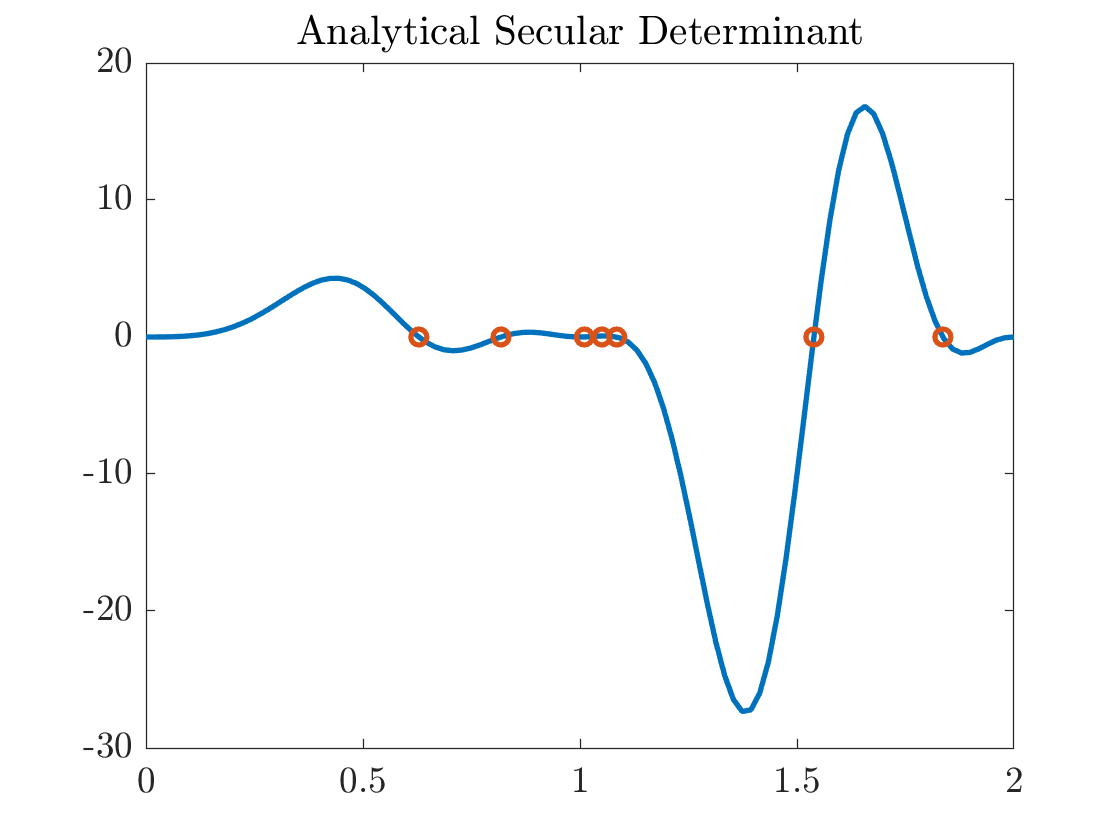

analyticF = matlabFunction(analyticSD);
analyticFx = analyticF(x);
figure
plot(x,analyticFx)
title('Analytical Secular Determinant')

% Finds zeros of F(x)
signChangesA=find(analyticFx(1:end-1).*analyticFx(2:end)<0);
nSignChangesA=length(signChangesA);
kstarA=zeros(nSignChangesA,1);
for n=1:nSignChangesA
    kstarA(n)=fzero(analyticF,x(signChangesA(n)+[0 1]));
end
m=length(kstarA);
min=islocalmin(Fx); min = find(min==1);
max=islocalmax(Fx); max = find(max==1);
minmax=union(min,max);
i=1;
doubleRoots=NaN;
for n=1:length(minmax)
    if abs(F(x(minmax(n))))<10^(-2)
        doubleRoots(i)=x(minmax(n));
        i=i+1;
    end
end
if ~isnan(doubleRoots)
    m = m + 2*length(doubleRoots);
    kstarA = union(kstarA,doubleRoots);
end
hold on
plot(kstarA,zeros(size(kstarA)),'o')

lambdaAnalytic = kstarA.^2;

We then create a plot comparing the two secular determinants and their roots.

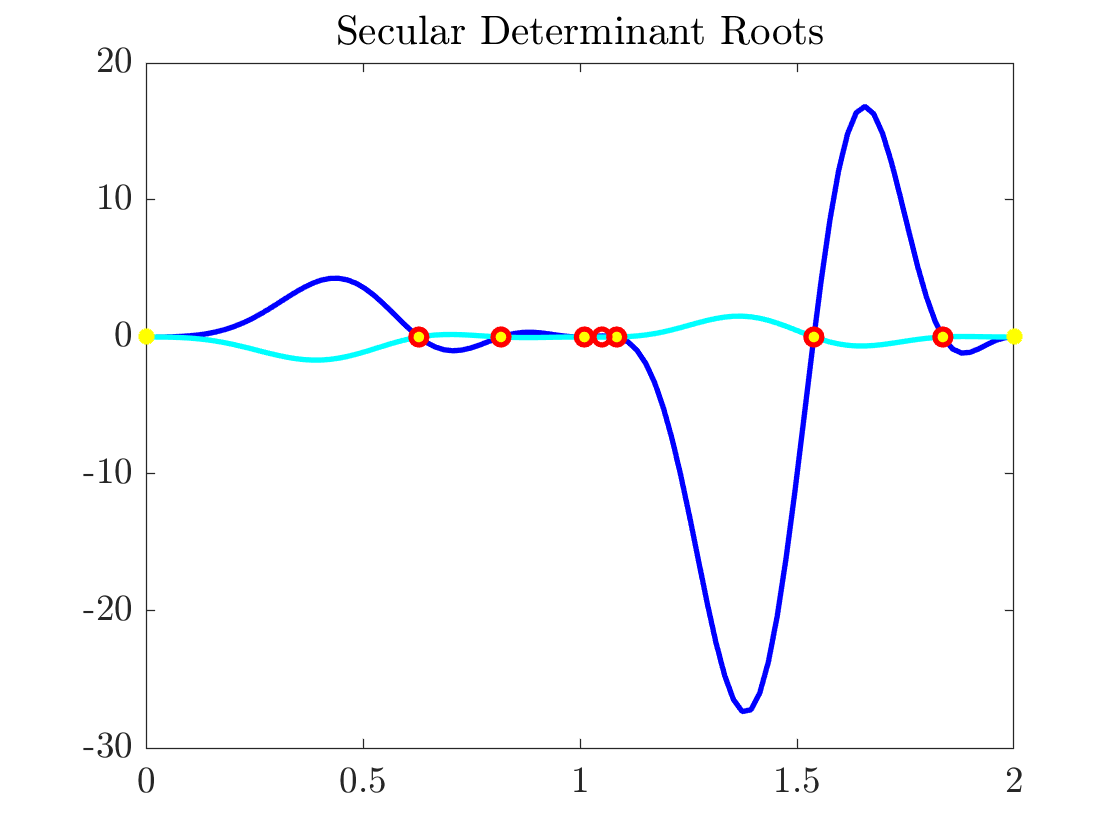

figure
plot(x,analyticFx,'color','b')
title('Secular Determinant Roots')
hold on
plot(x,Fx,'color','cyan')
hold on
plot(kstar,zeros(size(kstar)),'*','color','y')
hold on
plot(kstarA,zeros(size(kstarA)),'o','color','r')

## Compares secular determinant to Laplacian eigenvalue

Table of found lambda values. The column labels are shorthand for:

NSD: evals from the numerical SD

ASD: evals from the analytical SD

Cheb: evals from Chebyshev Laplacian

Uni: evals from uniform Laplacian

[~,lambda] = eigs(Phi,m+2);
lambda = uniquetol(lambda);
lambda = lambda(3:end);
sqrt(lambda);
[~,lambdaU] = eigs(PhiU,m+2);
lambdaU = uniquetol(lambdaU);
lambdaU = -flip(lambdaU(3:end));
sqrt(lambdaU);

A = [lambdaNumerical(1:7)'; lambdaAnalytic'; lambda'; lambdaU'];

T = array2table(A','VariableNames', ...
    {'NSD','ASD','Cheb','Uni'})

T = 7×4 table
      NSD        ASD       Cheb       Uni  
    _______    _______    ______    _______

          0    0.39522    0.4614    0.13524
    0.39522    0.66898         1    0.15818
    0.66898     1.0203    1.1131    0.48708
     1.0203     1.1036    1.4901    0.99998
     1.1764     1.1764    2.3725     1.2915
     2.3681     2.3681    3.7587     1.6118
     3.3714     3.3714         4     2.3745


Compare zeros of SD (represented on plot) to the sqrt of the evals. They should be the same!

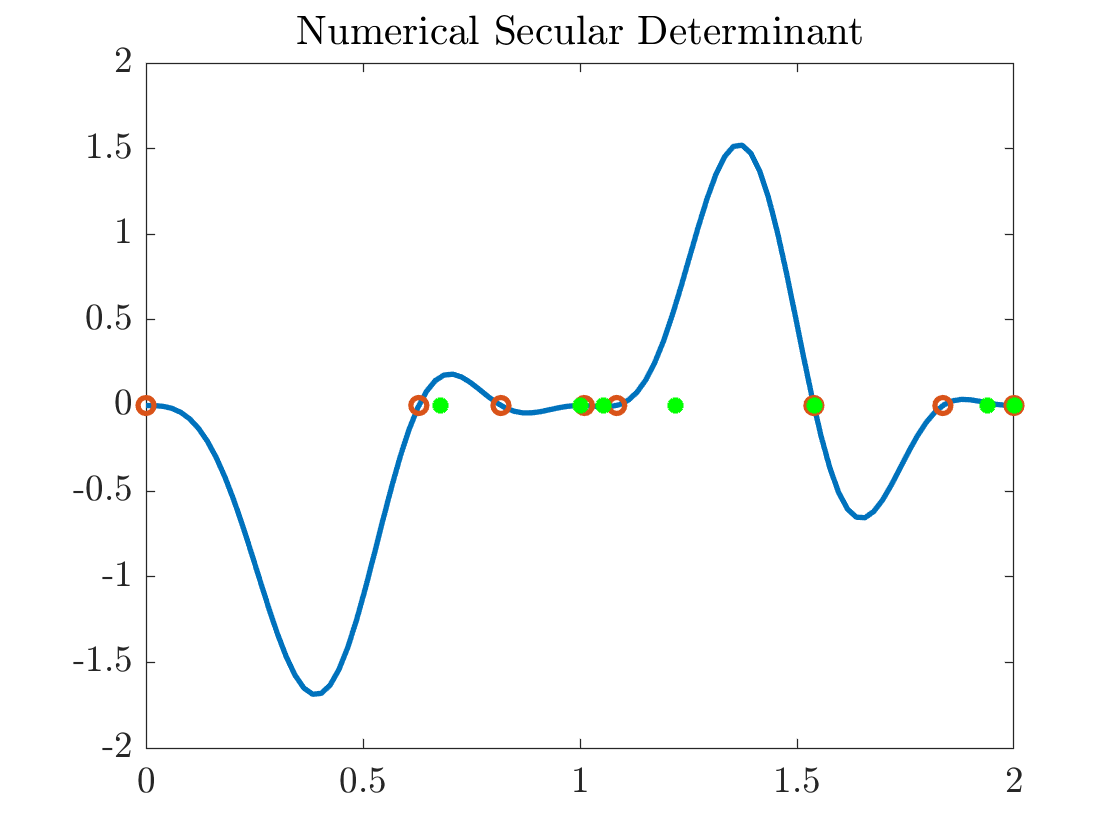

figure
plot(x,Fx)
title('Numerical Secular Determinant')
hold on
plot(kstar,zeros(size(kstar)),'o')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')

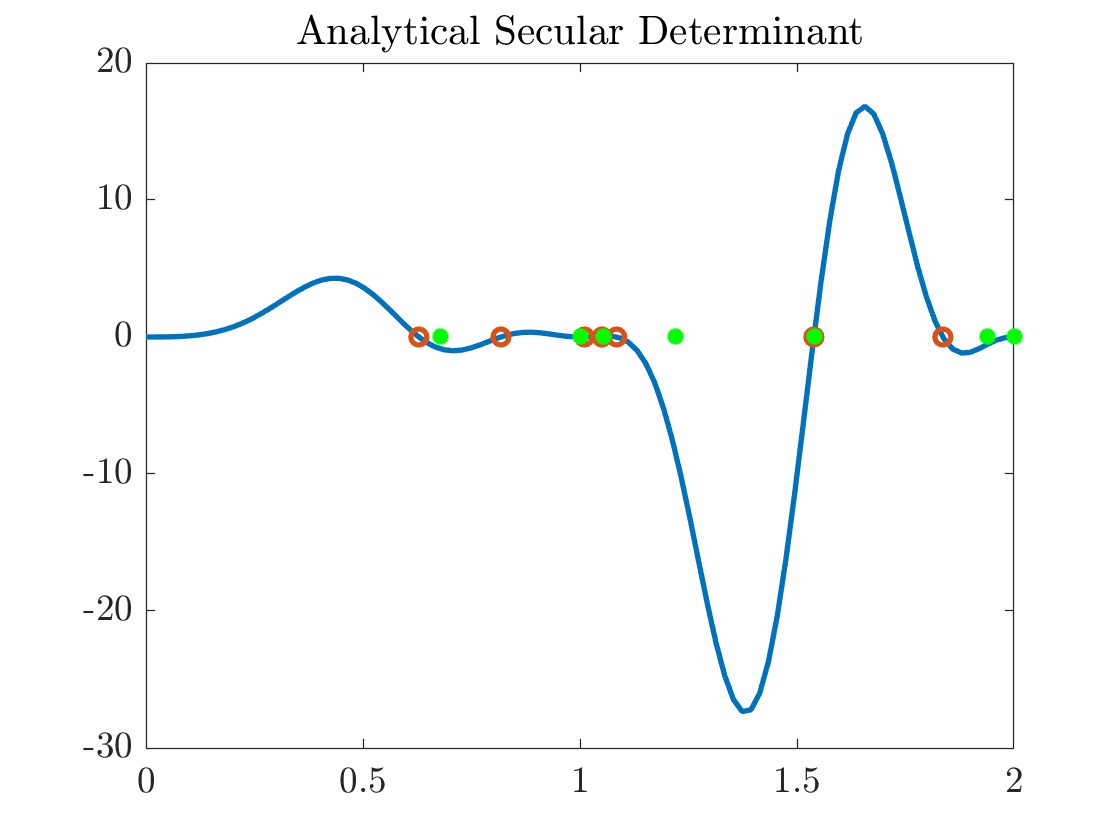



figure
plot(x,analyticFx)
title('Analytical Secular Determinant')
hold on
plot(kstarA,zeros(size(kstarA)),'o')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')